## 1D field visualization

TODO

- add GAUSS, LINEAR

- interp not working

- lower the grid resolution

generate map

grid = OctoGrid(2,2,2,10);

% add wall
grid.addBox(0.7,0.8,0,0.8,0.2,1.5)

generate phase

y = 0.4:0.001:1.3

y =     0.4000    0.4010    0.4020    0.4030    0.4040    0.4050    0.4060    0.4070    0.4080    0.4090    0.4100    0.4110    0.4120    0.4130    0.4140    0.4150    0.4160    0.4170    0.4180    0.4190    0.4200    0.4210    0.4220    0.4230    0.4240    0.4250    0.4260    0.4270    0.4280    0.4290    0.4300    0.4310    0.4320    0.4330    0.4340    0.4350    0.4360    0.4370    0.4380    0.4390    0.4400    0.4410    0.4420    0.4430    0.4440    0.4450    0.4460    0.4470    0.4480    0.4490


sample map

map_list = [];

x = 1;
z = 1;

% list of obstacle values
map_list = [map_list grid.grid(ceil(y*grid.resolution), x*grid.resolution, z*grid.resolution)];

draw map plot

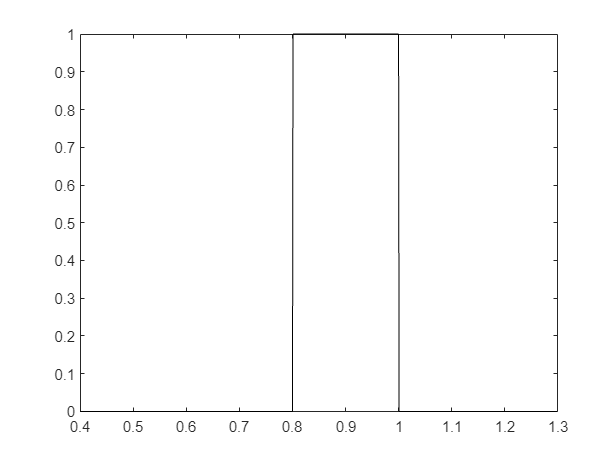

figure()
plot(y, map_list,'black')
hold on

generate kernels

rep_kernels = REP_kernels();

sigma = 2

draw grid on plot the size of resolution

generate LINEAR, GAUSS, LINEAR+INTERP, GAUSS+INTERP samples

rep_values = [];
tic()
for i = y
    rep_values = [rep_values REP_field_calculation(grid, rep_kernels, [x,i,z])'];
end
toc()

Elapsed time is 0.234665 seconds.


REP_field_calculation(grid, rep_kernels, [x,0.7,z])'

ans =    -0.5339
   -9.3581
    0.0000


plot samples

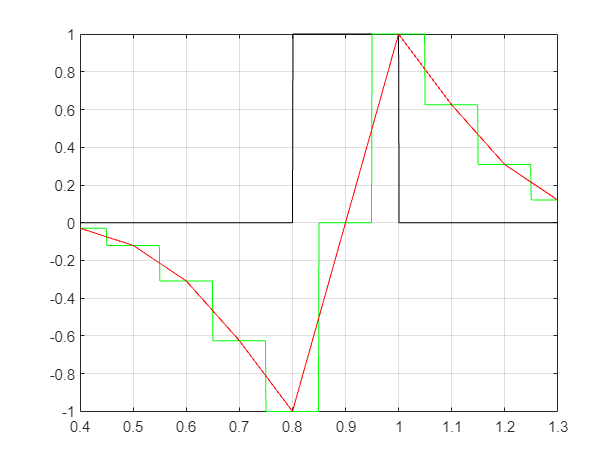

plot(y, (rep_values(2,:))/max(rep_values(2,:)),'red')
grid on
hold on

add legend